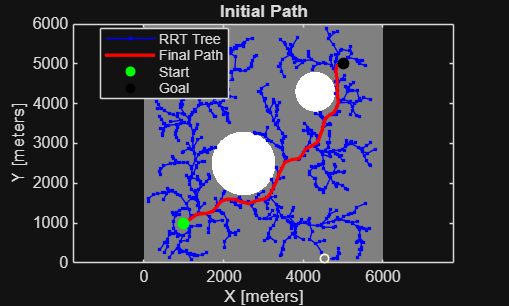

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         402    3.311367e+04     1.579e+02     1.000e+00     0.000e+00     1.338e+02  
    1         804    8.861924e+03     2.013e+02     1.000e+00     6.215e+02     1.244e+04  
    2        1208    1.223221e+04     1.066e+02     4.900e-01     5.468e+02     1.231e+04  
    3        1613    1.563490e+04     8.184e+01     3.430e-01     2.350e+02     1.857e+04  
    4        2017    2.298948e+04     5.498e+01     4.900e-01     2.324e+02     1.564e+04  
    5        2421    2.616633e+04     5.149e+01     4.900e-01     1.917e+02     1.916e+04  
    6        2825    2.469085e+04     4.444e+01     4.900e-01     2.092e+02     1.267e+04  
    7        3228    2.368925e+04     7.271e+01     7.000e-01     2.633e+02     6.598e+03  
    8        3632    2.269664e+04     5.227e+01     4.900e-01     1.265e+02     4.

clear; clc; close all;

sol = solve_uav_ocp_trapezoidal_complex();

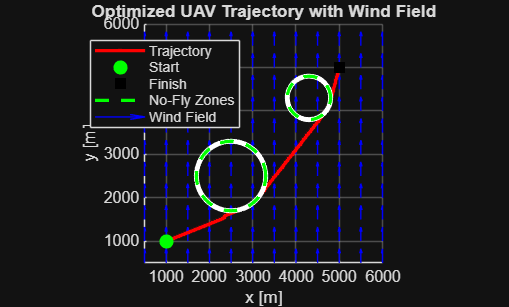


% Unpack solution:
tf_opt    = sol.tf;
x_opt     = sol.x;
y_opt     = sol.y;
V_opt     = sol.V;
theta_opt = sol.theta;
t         = sol.t;

% Define known problem parameters:
x0 = 1000; y0 = 1000;
xf = 5000; yf = 5000;
C1 = [2500, 2500]; L1 = 800;
C2 = [4300, 4300]; L2 = 500;

% Wind field parameters 
W  = 5;        % m/s
Wd = pi/2;     % radians

% Plot the optimized UAV trajectory with no-fly zones and wind vectors:
figure("Name", "Optimized UAV Trajectory");
hold on; axis equal; grid on;

% Wind vector field 
xGrid = 0:500:6000;
yGrid = 0:500:6000;
[Xw, Yw] = meshgrid(xGrid, yGrid);

Ux = W * cos(Wd) * ones(size(Xw));   % x-component of wind
Uy = W * sin(Wd) * ones(size(Yw));   % y-component of wind

% Plot wind vectors; the last argument is a scaling factor for arrow length
hWind = quiver(Xw, Yw, Ux, Uy, 0.5, 'b');

% UAV trajectory
hTrajectory = plot(x_opt, y_opt, 'r.-', 'LineWidth', 2);  % Optimized path

% Start and finish
hStart  = plot(x0, y0, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8);  % Start point
hFinish = plot(xf, yf, 'ks', 'MarkerFaceColor', 'k', 'MarkerSize', 8);  % Finish point

% No-fly zones:
viscircles(C1, L1, 'Color', 'g', 'LineStyle', '--');
viscircles(C2, L2, 'Color', 'g', 'LineStyle', '--');
% Dummy handle for no-fly zones (for legend)
hNoFly = plot(NaN, NaN, 'g--', 'LineWidth', 2);

xlabel('x [m]');
ylabel('y [m]');
title('Optimized UAV Trajectory with Wind Field');

legend([hTrajectory, hStart, hFinish, hNoFly, hWind], ...
       {'Trajectory','Start','Finish','No-Fly Zones','Wind Field'}, ...
       'Location','best');
xlim([500 6000])
ylim([500 6000])
hold off;

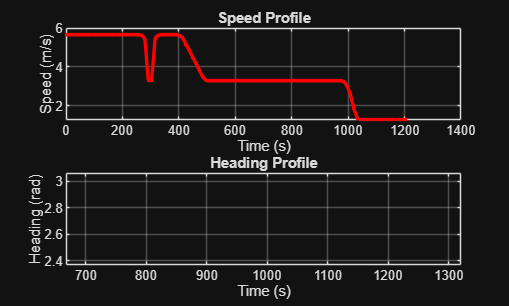


% Plot the state and control profiles:
figure("Name", "State and Control Profiles");

subplot(2,1,1);
plot(t, V_opt, 'r.-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Speed Profile');
grid on;

subplot(2,1,2);
theta_plot = unwrap(theta_opt);  % remove jumps for display
plot(t, theta_plot, 'm.-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Heading (rad)');
title('Heading Profile');
grid on;



disp(tf_opt)

   1.2023e+03




function sol = solve_uav_ocp_trapezoidal_complex()
    % Problem Parameters
    N = 100;              % number of discretization nodes
    x0 = 1000; y0 = 1000; % start position
    xf = 5000; yf = 5000; % finish position

    % Speed limits:
    Vmin = 0;
    Vmax = 10;

    % Wind field
    W  = 5;         % m/s (wind speed)
    Wd = pi/2;      % radians (wind direction)

    % No-fly zones
    C1 = [2500, 2500]; L1 = 800;
    C2 = [4300, 4300]; L2 = 500;

    %Generate Initial Guess
    mapSize = 6000;
    resolution = 1;
    occMap = occupancyMap(mapSize, mapSize, resolution);

    fillCircle(occMap, C1, L1);
    fillCircle(occMap, C2, L2);
    occMap.FreeThreshold = occMap.OccupiedThreshold;

    start_pose = [x0, y0, 0];
    goal_pose  = [xf, yf, 0];

    ss = stateSpaceDubins;
    ss.MinTurningRadius = 150;
    ss.StateBounds = [0, mapSize; 0, mapSize; -pi, pi];
    sv = validatorOccupancyMap(ss);
    sv.Map = occMap;
    sv.ValidationDistance = 1.0;

    planner = plannerRRT(ss, sv);
    planner.MaxConnectionDistance = 200;
    planner.MaxIterations = 5000;
    rng(0, 'twister');
    [pthObj, solnInfo] = planner.plan(start_pose, goal_pose);

    if isempty(pthObj)
        error('No path found by RRT, adjust parameters');
    end

    % Plot the RRT Solved Path
    figure("Name", "Initial Path");
    show(occMap);
    hold on;
    axis equal;
    title('Initial Path');
    if isfield(solnInfo, 'TreeData')
        plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-b', 'DisplayName', 'RRT Tree');
    end
    plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2, 'DisplayName', 'Final Path');
    scatter(start_pose(1), start_pose(2), 50, 'go', 'filled', 'DisplayName', 'Start');
    scatter(goal_pose(1), goal_pose(2), 50, 'ko', 'filled', 'DisplayName', 'Goal');
    legend('Location', 'best');
    hold off;

    % Interpolate the RRT path to obtain N nodes for initialization
    states_rrt = pthObj.States;
    dists = sqrt(diff(states_rrt(:,1)).^2 + diff(states_rrt(:,2)).^2);
    arc_length = [0; cumsum(dists)];
    total_length = arc_length(end);
    s_sample = linspace(0, total_length, N)';
    x_guess = interp1(arc_length, states_rrt(:,1), s_sample);
    y_guess = interp1(arc_length, states_rrt(:,2), s_sample);
    theta_guess = interp1(arc_length, states_rrt(:,3), s_sample);
    V_guess = 5 * ones(N, 1);
    tf0 = total_length / 5;

    % Build the Decision Vector
    nvar = 1 + 4*N;
    z0 = [tf0; x_guess; y_guess; V_guess; theta_guess];

    % Set Bounds
    lb = -inf(nvar, 1);
    ub = inf(nvar, 1);
    lb(1) = 1;
    V_idx = (2*N+2):(3*N+1);
    lb(V_idx) = Vmin;
    ub(V_idx) = Vmax;
    theta_idx = (3*N+2):(4*N+1);
    lb(theta_idx) = -pi;
    ub(theta_idx) = pi;

    % Setup and Solve using fmincon
    options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp', ...
        'MaxFunctionEvaluations', 5e5, 'MaxIterations', 5000, ...
        'OptimalityTolerance', 1e-6, 'ConstraintTolerance', 1e-3, 'StepTolerance', 1e-8);
    problem.objective = @(z) trapezoidal_objective(z, N);
    problem.x0 = z0;
    problem.nonlcon = @(z) trapezoidal_constraints(z, N, x0, y0, xf, yf, W, Wd, C1, L1, C2, L2);
    problem.lb = lb;
    problem.ub = ub;
    problem.options = options;
    problem.solver = 'fmincon';

    [z_opt, fval, exitflag, output] = fmincon(problem);

    % Extract and Return the Solution
    tf_opt = z_opt(1);
    x_opt = z_opt(2:N+1);
    y_opt = z_opt(N+2:2*N+1);
    V_opt = z_opt(2*N+2:3*N+1);
    theta_opt = z_opt(3*N+2:4*N+1);
    t = linspace(0, tf_opt, N)';

    sol.tf = tf_opt;
    sol.x = x_opt;
    sol.y = y_opt;
    sol.V = V_opt;
    sol.theta = theta_opt;
    sol.t = t;
end

function J = trapezoidal_objective(z, N)
    tf = z(1);
    V = z(2*N+2:3*N+1);
    theta = z(3*N+2:4*N+1);

    dt = tf/(N-1);

    % Original cost: integral of V^2
    J_base = dt/2 * (V(1)^2 + 2*sum(V(2:end-1).^2) + V(end)^2);

    % smoothness penalties
    dV     = diff(V);
    dtheta = diff(theta);

    alpha_V     = 1;  
    alpha_theta = 1;

    J_smooth = alpha_V * sum(dV.^2) + alpha_theta * sum(dtheta.^2);

    J = J_base + J_smooth;
end


function [c, ceq] = trapezoidal_constraints(z, N, x0, y0, xf, yf, W, Wd, C1, L1, C2, L2)
    tf = z(1);
    x = z(2:N+1);
    y = z(N+2:2*N+1);
    V = z(2*N+2:3*N+1);
    theta = z(3*N+2:4*N+1);
    dt = tf/(N-1);
    
    ceq = [];
    for k = 1:N-1
        f_x_k = V(k)*sin(theta(k)) + W*cos(Wd);
        f_x_kp1 = V(k+1)*sin(theta(k+1)) + W*cos(Wd);
        f_y_k = V(k)*cos(theta(k)) + W*sin(Wd);
        f_y_kp1 = V(k+1)*cos(theta(k+1)) + W*sin(Wd);
        
        ceq = [ceq;
               x(k+1) - x(k) - dt/2*(f_x_k + f_x_kp1);
               y(k+1) - y(k) - dt/2*(f_y_k + f_y_kp1)];
    end
    
    ceq = [ceq;
           x(1) - x0;
           y(1) - y0;
           x(end) - xf;
           y(end) - yf];
       
    c = [];
    for k = 1:N
        c = [c;
             L1^2 - ((x(k)-C1(1))^2 + (y(k)-C1(2))^2);
             L2^2 - ((x(k)-C2(1))^2 + (y(k)-C2(2))^2)];
    end
end

function fillCircle(occMap, center, radius)
    xLimits = occMap.XWorldLimits;
    yLimits = occMap.YWorldLimits;
    gridSize = occMap.GridSize;
    
    xCenters = linspace(xLimits(1), xLimits(2), gridSize(2));
    yCenters = linspace(yLimits(1), yLimits(2), gridSize(1));
    [X, Y] = meshgrid(xCenters, yCenters);
    
    mask = ((X - center(1)).^2 + (Y - center(2)).^2) <= radius^2;
    occupiedCells = [X(mask), Y(mask)];
    setOccupancy(occMap, occupiedCells, 1);
end

